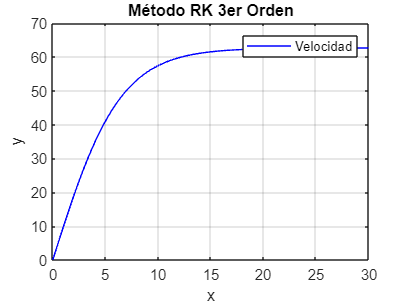

clc
clear
close all


h = 0.1;

Cd = 0.225;
g= 9.81;
m = 90;
f = @(x,v) g-Cd/m*v^2;
x0 = 0;
xf = 30;
v0 = 0;

n = ((xf - x0) / h);

t = zeros(n+1, 1);
v = zeros(n+1, 1);

t(1) = x0;
v(1) = v0;
y(1) = 1000;

for i = 1:n
    k1 = f(t(i), v(i));
    k2 = f(t(i) + 1/2*h, v(i) + (1/2*k1*h));
    k3 = f(t(i) + h, v(i)-k1*h + 2*k2*h);    
    % valores de v
    v(i+1) = v(i) + 1/6*(k1+(4*k2)+k3)*h;

    t(i+1) = t(i) + h;
    
    k1 = f(t(i), y(i));
    k2 = f(t(i) + 1/2*h, y(i) + (1/2*k1*h));
    k3 = f(t(i) + h, y(i)-k1*h + 2*k2*h); 
    % valores de y (posición)
    y(i+1) = y(i) + 1/6*(k1+(4*k2)+k3)*h;

    t(i+1) = t(i) + h;
   
end

%Gráfica de la velocidad
plot(t, v, 'b-');
xlabel('x');
ylabel('y');
title('Método RK 3er Orden');
grid on;
legend('Velocidad')

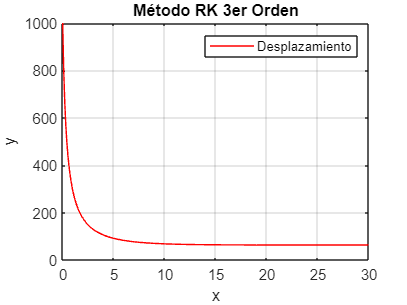


%Gráfica de posición o desplazamiento
plot(t, y, 'r-');
xlabel('x');
ylabel('y');
title('Método RK 3er Orden');
grid on;
legend ('Desplazamiento')